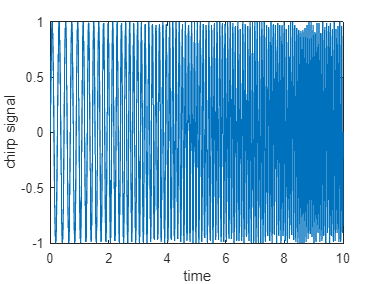

%Question 1.1
F=linspace(4,10,1000);
t=linspace(0,10,1000);
y=sin(2*pi.*F.*t);
plot(t,y)

xlabel("time")
ylabel("chirp signal")

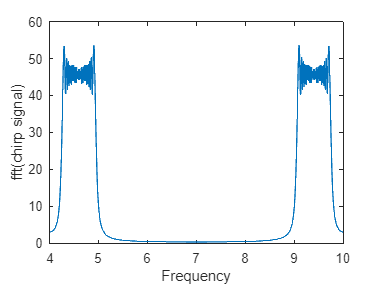

%Question 1.2
figure;
plot(F,abs(fft(y)))

xlabel("Frequency")
ylabel("fft(chirp signal)")

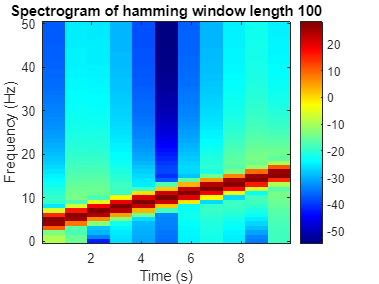

%Question 1.3
window_length = 100;  % Window size in samples
overlap = 10;         % Overlap between consecutive windows in samples
nfft = 100;           % Number of FFT points (usually equal to window_length for better resolution)
[S, f,t] = spectrogram(y, hamming(window_length), overlap, nfft, 100);
figure;
imagesc(t,f, 20*log10(abs(S)));
axis xy;  % Flip the Y-axis to have lower frequencies at the bottom
colormap('jet');  % You can choose a different colormap if you prefer
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Spectrogram of hamming window length 100');
colorbar;  % Add a colorbar to show magnitude values

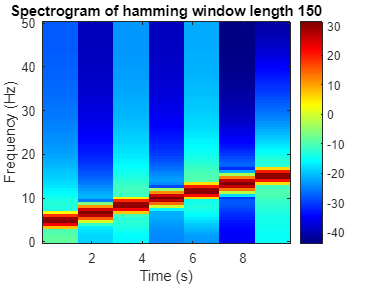

window_length = 150;  % Window size in samples
overlap = 10;         % Overlap between consecutive windows in samples
nfft = 150;           % Number of FFT points (usually equal to window_length for better resolution)
[S, f,t] = spectrogram(y, hamming(window_length), overlap, nfft, 100);
figure;
imagesc(t,f, 20*log10(abs(S)));
axis xy;  % Flip the Y-axis to have lower frequencies at the bottom
colormap('jet');  % You can choose a different colormap if you prefer
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Spectrogram of hamming window length 150');
colorbar;  % Add a colorbar to show magnitude values

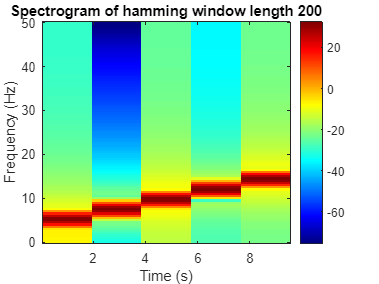

window_length = 200;  % Window size in samples
overlap = 10;         % Overlap between consecutive windows in samples
nfft = 200;           % Number of FFT points (usually equal to window_length for better resolution)
[S, f,t] = spectrogram(y, hamming(window_length), overlap, nfft, 100);
figure;
imagesc(t,f, 20*log10(abs(S)));
axis xy;  % Flip the Y-axis to have lower frequencies at the bottom
colormap('jet');  % You can choose a different colormap if you prefer
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Spectrogram of hamming window length 200');
colorbar;  % Add a colorbar to show magnitude values

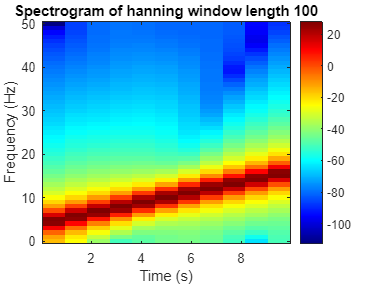

window_length = 100;  % Window size in samples
overlap = 10;         % Overlap between consecutive windows in samples
nfft = 100;           % Number of FFT points (usually equal to window_length for better resolution)
[S, f,t] = spectrogram(y, hanning(window_length), overlap, nfft, 100);
figure;
imagesc(t,f, 20*log10(abs(S)));
axis xy;  % Flip the Y-axis to have lower frequencies at the bottom
colormap('jet');  % You can choose a different colormap if you prefer
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Spectrogram of hanning window length 100');
colorbar;  % Add a colorbar to show magnitude values

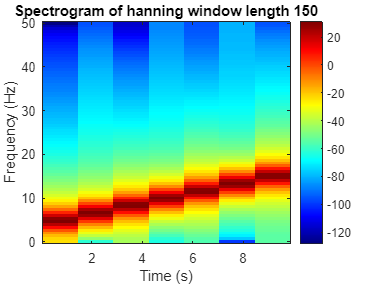

window_length = 150;  % Window size in samples
overlap = 10;         % Overlap between consecutive windows in samples
nfft = 150;           % Number of FFT points (usually equal to window_length for better resolution)
[S, f,t] = spectrogram(y, hanning(window_length), overlap, nfft, 100);
figure;
imagesc(t,f, 20*log10(abs(S)));
axis xy;  % Flip the Y-axis to have lower frequencies at the bottom
colormap('jet');  % You can choose a different colormap if you prefer
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Spectrogram of hanning window length 150');
colorbar;  % Add a colorbar to show magnitude values

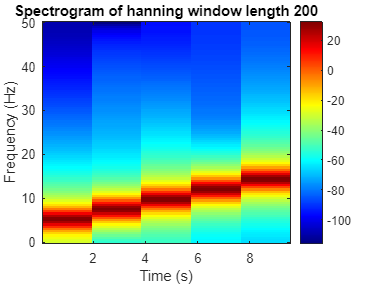

window_length = 200;  % Window size in samples
overlap = 10;         % Overlap between consecutive windows in samples
nfft = 200;           % Number of FFT points (usually equal to window_length for better resolution)
[S, f,t] = spectrogram(y, hanning(window_length), overlap, nfft, 100);
figure;
imagesc(t,f, 20*log10(abs(S)));
axis xy;  % Flip the Y-axis to have lower frequencies at the bottom
colormap('jet');  % You can choose a different colormap if you prefer
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Spectrogram of hanning window length 200');
colorbar;  % Add a colorbar to show magnitude values

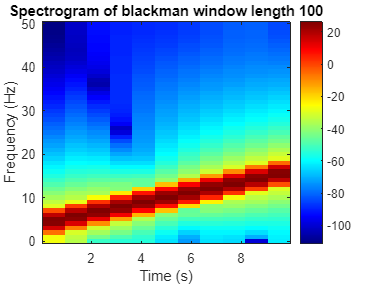

window_length = 100;  % Window size in samples
overlap = 10;         % Overlap between consecutive windows in samples
nfft = 100;           % Number of FFT points (usually equal to window_length for better resolution)
[S, f,t] = spectrogram(y, blackman(window_length), overlap, nfft, 100);
figure;
imagesc(t,f, 20*log10(abs(S)));
axis xy;  % Flip the Y-axis to have lower frequencies at the bottom
colormap('jet');  % You can choose a different colormap if you prefer
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Spectrogram of blackman window length 100');
colorbar;  % Add a colorbar to show magnitude values

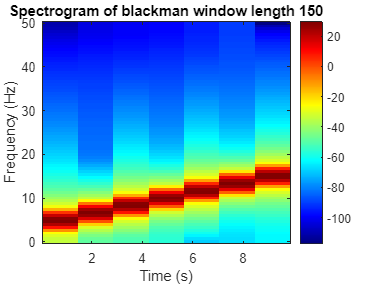

window_length = 150;  % Window size in samples
overlap = 10;         % Overlap between consecutive windows in samples
nfft = 150;           % Number of FFT points (usually equal to window_length for better resolution)
[S, f,t] = spectrogram(y, blackman(window_length), overlap, nfft, 100);
figure;
imagesc(t,f, 20*log10(abs(S)));
axis xy;  % Flip the Y-axis to have lower frequencies at the bottom
colormap('jet');  % You can choose a different colormap if you prefer
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Spectrogram of blackman window length 150');
colorbar;  % Add a colorbar to show magnitude values

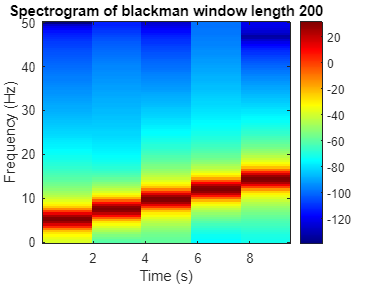

window_length = 200;  % Window size in samples
overlap = 10;         % Overlap between consecutive windows in samples
nfft = 200;           % Number of FFT points (usually equal to window_length for better resolution)
[S, f,t] = spectrogram(y, blackman(window_length), overlap, nfft, 100);
figure;
imagesc(t,f, 20*log10(abs(S)));
axis xy;  % Flip the Y-axis to have lower frequencies at the bottom
colormap('jet');  % You can choose a different colormap if you prefer
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Spectrogram of blackman window length 200');
colorbar;  % Add a colorbar to show magnitude values

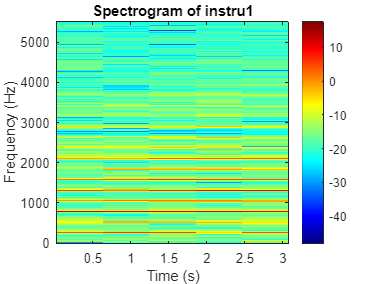

%Question 2.1
[y1, Fs] = audioread('instru1.wav');
window_length = 7250;  % Window size in samples
overlap = 512;         % Overlap between consecutive windows in samples
nfft = 7250;           % Number of FFT points (usually equal to window_length for better resolution)
[S, f, t] = spectrogram(y1, hamming(window_length), overlap, nfft, Fs);
figure;
imagesc(t, f, 10*log10(abs(S)));
axis xy;  % Flip the Y-axis to have lower frequencies at the bottom
colormap('jet');  % You can choose a different colormap if you prefer
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Spectrogram of instru1');
colorbar;  % Add a colorbar to show magnitude values

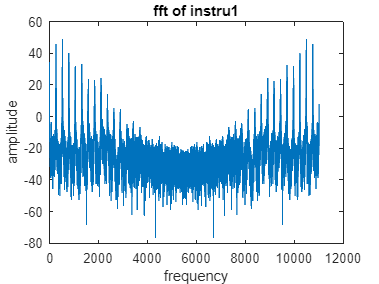


figure;
fft_opera=abs(fft(y1));
freqs = (0:length(fft(y1))-1) * (Fs /length(fft(y1))); Freq=freqs;
plot(Freq,20*log10(fft_opera))
title("fft of instru1")
xlabel("frequency")
ylabel("amplitude")

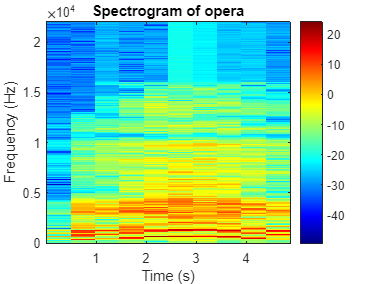

%Question 2.2
[y2, Fs] = audioread('Opera.wav');
window_length = 22000;  % Window size in samples
overlap = 512;         % Overlap between consecutive windows in samples
nfft = 22000;           % Number of FFT points (usually equal to window_length for better resolution)
[S, f, t] = spectrogram(y2, hamming(window_length), overlap, nfft, Fs);
figure;
imagesc(t, f, 10*log10(abs(S)));
axis xy;  % Flip the Y-axis to have lower frequencies at the bottom
colormap('jet');  % You can choose a different colormap if you prefer
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Spectrogram of opera');
colorbar;  % Add a colorbar to show magnitude values

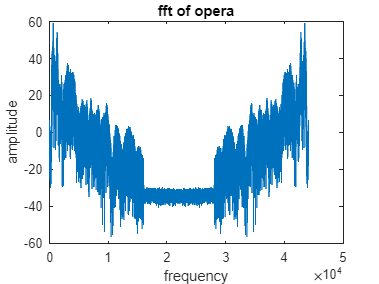


figure;
fft_opera=abs(fft(y2));
freqs = (0:length(fft(y2))-1) * (Fs /length(fft(y2))); Freq=freqs;
plot(Freq,20*log10(fft_opera))
title("fft of opera")
xlabel("frequency")
ylabel("amplitude")

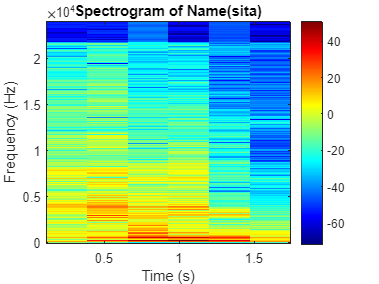

%question 3
filename = 'Name1.mp4';
[audio, sampleRate] = audioread(filename);
[S, F, T] = spectrogram(audio,hamming(24000), 11000,512,Fs);
figure;
imagesc(T, F, 20*log10(abs(S))); % Convert to dB for better visualization
axis xy; % Flip the y-axis to have lower frequencies at the bottom
xlabel('Time (s)');
ylabel('Frequency (Hz)');
title('Spectrogram of Name(sita)');
colorbar ;
colormap('jet'); % You can choose a different colormap if desired